Lab Exercise 3.1

3.1 (a)

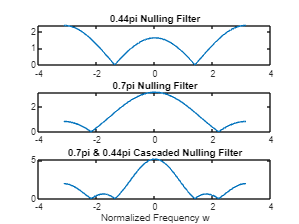

% (a)
clear;
close all;
ww = -pi:pi/100:pi;

figure; % figure for nulling filter subplots

b_044 = [1 -2*cos(0.44*pi) 1]; %0.44*pi nulling filter
H_044 = freqz(b_044,1,ww); %finding the frequency response
subplot(3,1,1);
plot(ww,abs(H_044));
title('0.44pi Nulling Filter');

b_07 = [1 -2*cos(0.7*pi) 1]; %0.7*pi nulling filter
H_07 = freqz(b_07,1,ww); %finding the frequency response
subplot(3,1,2);
plot(ww,abs(H_07));
title('0.7pi Nulling Filter');

b_res = conv(b_044,b_07); %cascading the filters using convoution
HH = freqz(b_res,1,ww); %finding the frequency response
subplot(3,1,3);
plot(ww,abs(HH));
title('0.7pi & 0.44pi Cascaded Nulling Filter');
xlabel('Normalized Frequency w');

3.1 (b)

% (b)
nn = 0:149; %150 samples
xx = 5*cos(0.3*pi*nn) + 22*cos(0.44*pi*nn-pi/3) + 22*cos(0.7*pi*nn-pi/4); % a signal that is the sum of 3 sinusoids

3.1 (c)

% (c) signal xx through cascaded filter
b_res = conv(b_044,b_07); %cascading the filters using convoution
HH = freqz(b_res,1,ww); %finding the frequency response

figure
subplot(4,1,1);
plot(nn,xx);
grid on;
title('Original Signal');

xx_filt = firfilt(b_res,xx);    % filtering the signal through the cascaded system
subplot(4,1,3);
plot(nn,xx_filt(1:length(nn)));
grid on;
title('Filtered Signal');

3.1 (d)

% (d) plot first 40 samples
n = 40; % size to show the signal
subplot(4,1,2);
plot(nn(1:n),xx_filt(1:n));
grid on;
title('First 40 Samples of Filtered Signal');
% instruction: calculate for the formula of the output signal by hand

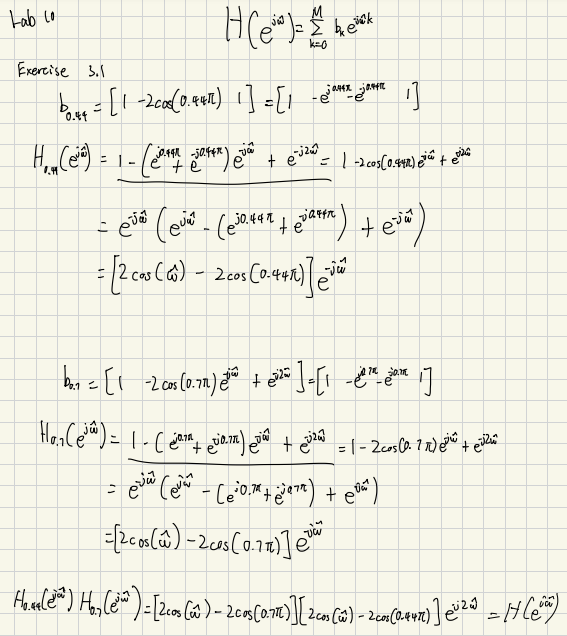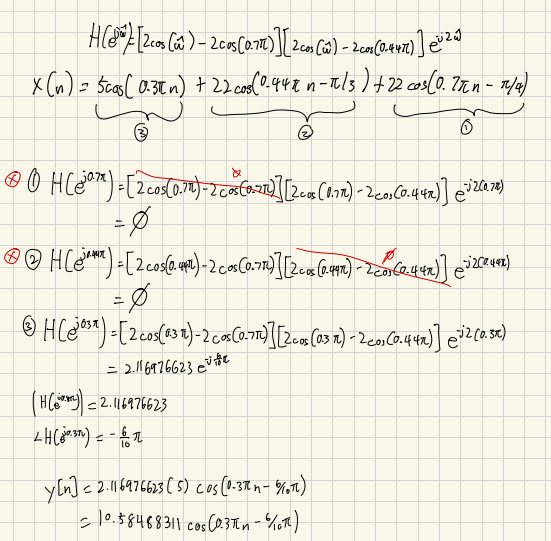

3.2 (e)

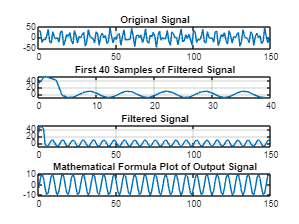

% (e) plot the mathematical formula
subplot(4,1,4);
yy = 10.58488311*cos(0.3*pi*nn-6/10*pi);
plot(nn,yy);
title('Mathematical Formula Plot of Output Signal')

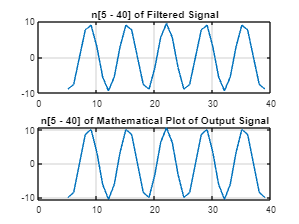

%%
figure 
t_i = 5; % start time of plot
n_i = t_i + 1; % start index of plot
n = 40; % size to show the plot
subplot(2,1,1);
plot(nn(n_i:n),xx_filt(n_i:n));
grid on;
title('n[5 - 40] of Filtered Signal');

subplot(2,1,2)
plot(nn(n_i:n),yy(n_i:n));
grid on;
title('n[5 - 40] of Mathematical Plot of Output Signal')

3.1 (f)

When performing convolution of a two systems, the resulting length of the cascaded system would be the sum of their length - 1, or length of a system plus the order of the other system. Reason for why the starting indices compared to the mathematical formula is different is because convolution at n < L or at n <= M is considering 0 values at n < 0, therefore the number of "startup points" to correspond to the mathematical formula is the order M or L - 1.

Lab Exercise 3.2

3.2 (a)

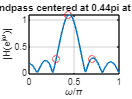

%% (a) 
close all;
clear;
wc=0.44*pi;
L = 10;

ww = [0.3*pi 0.44*pi 0.7*pi];
w = (0:pi/100:pi);

ww_index = [];

for i = 1:3
    ww_index = [ww_index  find(abs(w - ww(i)) < 0.00000001)];
end

w_pi = w/pi;
figure;
[HH,ww_abs] = bandfilt(wc,L,1,ww);
HH_abs = abs(HH); % magnitudes of HH
title('Bandpass centered at 0.44pi at L = 10')
hold on;
plot(w_pi(ww_index), HH_abs(ww_index),"r o"); % ww red o



fprintf('Magnitudes of the Normalized Frequencies:\n0.3pi: %.4f\n0.44pi: %.4f\n0.7pi: %.4f\n',ww_abs(1),ww_abs(2),ww_abs(3));

Magnitudes of the Normalized Frequencies:
0.3pi: 0.2836
0.44pi: 1.0961
0.7pi: 0.2861


% 0.3pi: 0.2836, 0.44pi: 1.0961, 0.7pi: 0.286

3.2 (b) L = 10

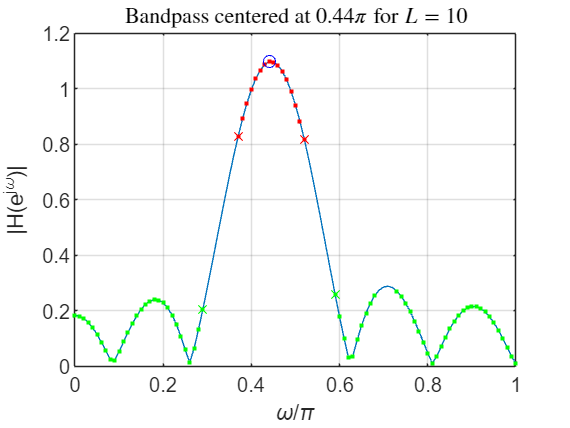

wc=0.44*pi; % function [HH]= bpf_bands(wc, L, plotyn)
L = 10;
w=0:pi/100:pi;

figure;
HH = bandfilt(wc,L,1);
title_str = sprintf('Bandpass centered at $%.2f\\pi$ for $L = %d$', wc/pi, L);
title(title_str, 'Interpreter', 'latex');
HH; % frequency response function at wc = 0.44*pi
HH_abs = abs(HH); % magnitudes of HH

% Finding H_max
H_max = max(HH_abs);
H_max_i = find(HH_abs == H_max); % finding index of H_max

% determining passband region
passband_region_index = find(HH_abs/H_max >= 1/sqrt(2));
passband_cutoff_index = [passband_region_index(1) passband_region_index(end)];
passband_cutoff_mag = [HH_abs(passband_cutoff_index(1)) HH_abs(passband_cutoff_index(end))];
passband_cutoff_freq = [w(passband_cutoff_index(1))/pi w(passband_cutoff_index(end))/pi];

% determining stopband region
first_stopband_region_index = find(HH_abs(1:passband_cutoff_index(1))/H_max < 1/4);
second_stopband_region_index = passband_cutoff_index(end) + find(HH_abs(passband_cutoff_index(end):length(HH_abs))/H_max < 1/4) - 1;
stopband_cutoff_index = [first_stopband_region_index(end) second_stopband_region_index(1)];
stopband_region_index = find(HH_abs/H_max < 1/4);

w_pi = w./pi;
hold on;
plot(w_pi(passband_cutoff_index), HH_abs(passband_cutoff_index),"r x"); % passband_cutoff red x
plot(w_pi(passband_region_index), HH_abs(passband_region_index),"r ."); % passband_region red .
plot(w_pi(H_max_i), HH_abs(H_max_i),"o b"); % H_max blue circle


plot(w_pi(stopband_cutoff_index), HH_abs(stopband_cutoff_index),"x g") % plot stopband_cutoff green x
plot(w_pi(stopband_region_index), HH_abs(stopband_region_index),". g")  % plot stopband_region green .

3.2 (b) L = 20

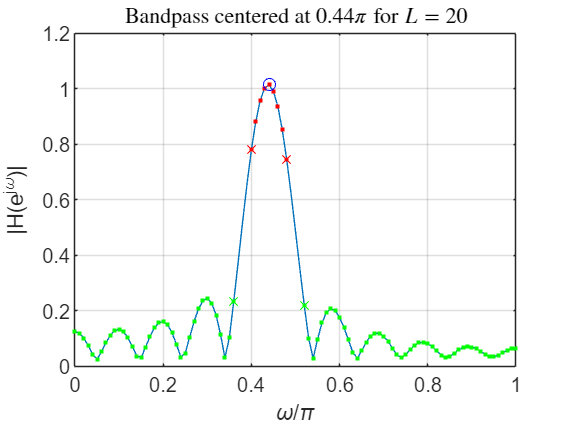

bpf_bands(0.44*pi, 20, 1);

3.2 (b) L = 40

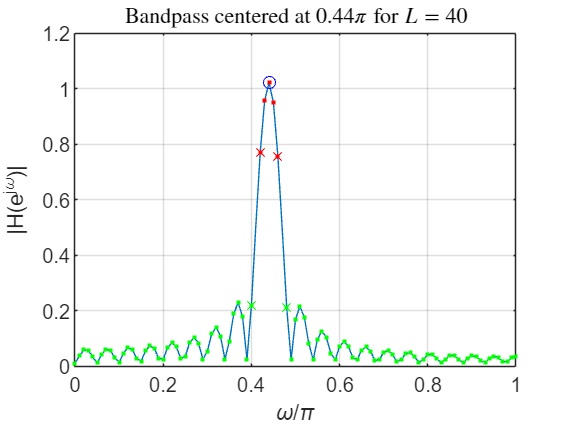

bpf_bands(0.44*pi, 40, 1);

3.2 (c)

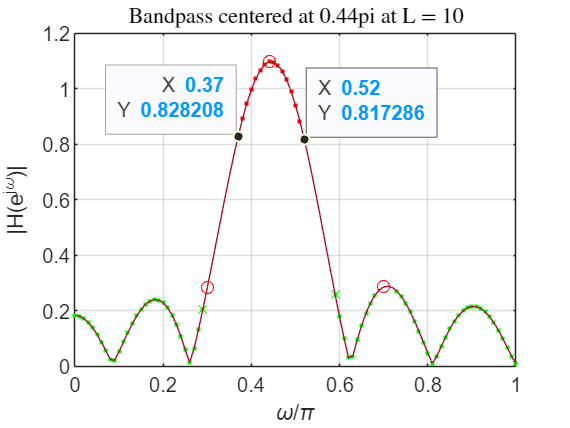

wc=0.44*pi;
L = 10;

figure;
ww = [0.3*pi 0.44*pi 0.7*pi];
bpf_bands(wc,L,1);
hold on;
[HH,ww_abs] = bandfilt(wc,L,1,ww);

title('Bandpass centered at 0.44pi at L = 10')

fprintf('Magnitudes of the Normalized Frequencies:\n0.3pi: %.4f\n0.44pi: %.4f\n0.7pi: %.4f\n',ww_abs(1),ww_abs(2),ww_abs(3));

Magnitudes of the Normalized Frequencies:
0.3pi: 0.2836
0.44pi: 1.0961
0.7pi: 0.2861


The frequency that are relatively unchanged are regions within the passbands, or in the region marked red (normalized frequencies from 0.37pi to 0.52pi). And that frequencies outside the passpand, and near (0.3pi) and within the pass (0.7pi) will have a significantly reduced magnitude.

3.2 (d) Approach - Loops

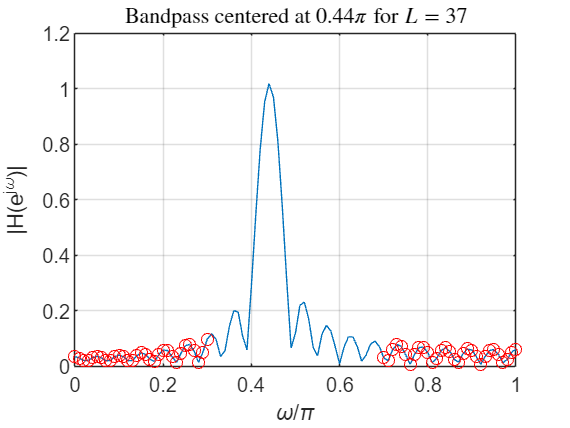

wc=0.44*pi;
%L = 10;
w1 = 0:pi/100:0.3*pi; % |w| <= 0.3pi
w2 = 0.7*pi:pi/100:pi; % 0.7pi <= |w| <= pi

ww = [w1 w2];
for i = 10:1:100
    L = i;
    [HH,ww_abs] = bandfilt(wc,i,0,ww);
    if max(ww_abs) <= 0.1
        break;
    end
end
figure;
bandfilt(wc,L,1,ww);
hold on;
title_str = sprintf('Bandpass centered at $%.2f\\pi$ for $L = %d$', wc/pi, L);
title(title_str, 'Interpreter', 'latex');
hold off;

fprintf('Smallest Length for less than a factor of 10 on\n[|w| <= 0.3pi] and [0.7pi <= |w| <= pi] is L = %d',L); % L = 37

Smallest Length for less than a factor of 10 on
[|w| <= 0.3pi] and [0.7pi <= |w| <= pi] is L = 37

3.2 (e)

nn = 0:99; %100 samples
xx = 5*cos(0.3*pi*nn) + 22*cos(0.44*pi*nn-pi/3) + 22*cos(0.7*pi*nn-pi/4); % a signal that is the sum of 3 sinusoids
xx_arr = [5*cos(0.3*pi*nn); 22*cos(0.44*pi*nn-pi/3); 22*cos(0.7*pi*nn-pi/4)];
ww = [0.3*pi 0.44*pi 0.7*pi];
figure;
subplot(2,1,1);
plot(nn,xx);
title('Input Signal');

% Filtering
L = 37;
wc=0.44*pi;
[HH,ww_abs,ww_angle,ww_HH] = bandfilt(wc,L,0,ww);
yy = 0;
for i = 1:length(ww_HH)
    yy = yy+ww_HH(i)*xx_arr(i,:);
end
%yy = ww_HH(1)*5*cos(0.3*pi*nn) + ww_HH(2)*22*cos(0.44*pi*nn-pi/3) + ww_HH(3)*22*cos(0.7*pi*nn-pi/4);
subplot(2,1,2);
plot(nn,yy(1:length(nn)));

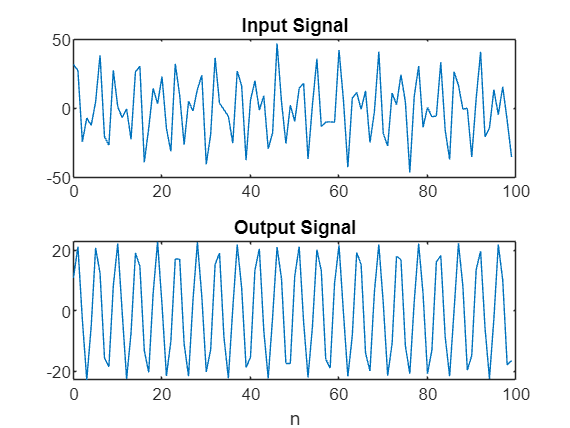

xlabel('n');
title('Output Signal');

`Magnitudes of the Normalized Frequencies:`

`0.3pi: 0.0983`

`0.44pi: 1.0186`

`0.7pi: 0.0317`

Given the following effects caused by the filter with respect to the given frequencies at (0.3pi, 0.44pi, and 0.7pi), their corresponding resulting magnitude is as above. The involvement of frequencies 0.3pi and 0.7pi are thus significantly smaller, this phenomenon can be observed in the graph that the output signal is overall less sporadic than the input signal, this is due to the lessen involvment of frequencies other than 0.44pi.

3.2 (f)

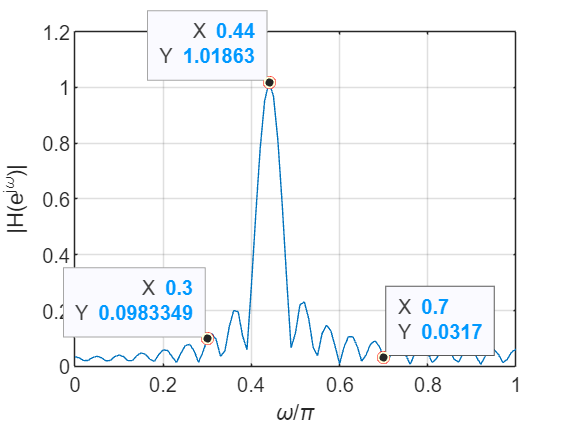

wc=0.44*pi;
L = 37;
ww = [0.3*pi 0.44*pi 0.7*pi];
figure;
bandfilt(wc,L,1,ww);

The frequency response function is a function of normalized frequency, in which when receives a corresponding input signal (which is the sum of pure form signals), extracted are which is the frequencies of the input signal, such that each frequency has a different magnitude (increased/reduced/rejected) output given the filter. The simplest explanation would be to understanding the frequency response magnitude plot. Encircled are the corresponding frequencies given in the example of problem 3.2 (e), each of the frequency have their corresponding reference on the plot, thus the result of a given signal at a certain frequency is relative to the magnitude given by the frequency response function.